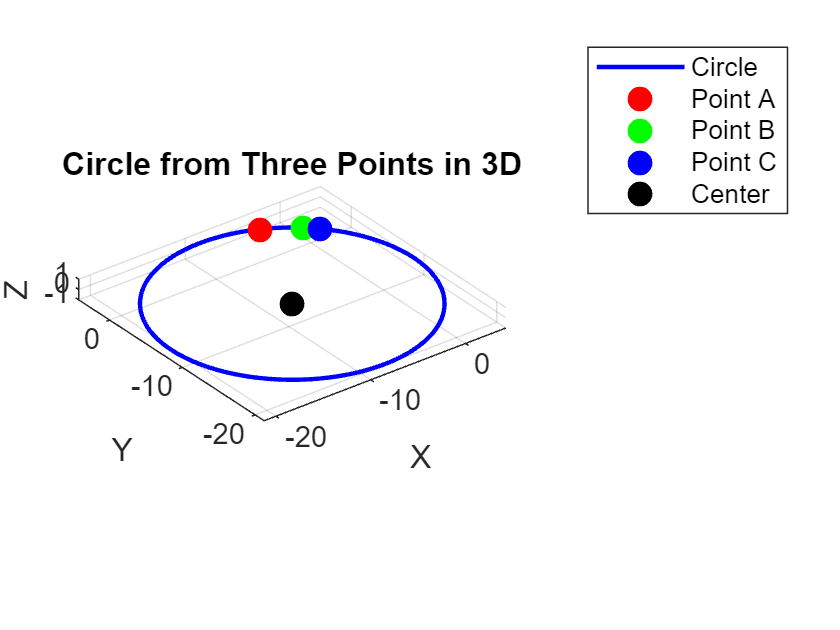

% Tạo các điểm mẫu
point3 = Point([1, 0, 0], [1 0 0 0], 'Frame1');
point2 = Point([0, 1, 0], [1 0 0 0], 'Frame2');
point1 = Point([-3, 3, 0], [1 0 0 0], 'Frame3');

% Gọi hàm để tính toán các thông số của đường tròn từ ba điểm
[circleCenter, circleRadius, angleBetweenPoints, isClockwise] = circleFromThreePoints(point1, point2, point3);
plotCircle3D(circleCenter,circleRadius,point1, point2, point3);

% Hiển thị kết quả
disp('Thông số của đường tròn từ ba điểm:');

Thông số của đường tròn từ ba điểm:


disp(['Tọa độ tâm: ', num2str(circleCenter)]);

Tọa độ tâm: -8.5        -8.5           0


disp(['Bán kính: ', num2str(circleRadius)]);

Bán kính: 12.7475


disp(['Góc giữa các điểm (radians): ', num2str(angleBetweenPoints)]);

Góc giữa các điểm (radians): 22.6199


disp(['Chiều quay (Clockwise): ', num2str(isClockwise)]);

Chiều quay (Clockwise): 1



% Tạo điểm và tâm để kiểm tra hàm thứ hai
startPoint = Point([1, 1, 0], [1 0 0 0], 'Frame1');
endPoint = Point([4, 1, 0], [1 0 0 0], 'Frame2');
centerPoint = Point([2.5, 2.5, 0], [1 0 0 0], 'FrameCenter');

% Gọi hàm để tính toán các thông số của đường tròn từ hai điểm và tâm
[circleRadius2, angleBetweenPoints2, isClockwise2] = circleFromTwoPointsAndCenter(startPoint, endPoint, centerPoint);

% Hiển thị kết quả
disp('Thông số của đường tròn từ hai điểm và tâm:');

Thông số của đường tròn từ hai điểm và tâm:


disp(['Bán kính: ', num2str(circleRadius2)]);

Bán kính: 2.1213


disp(['Góc giữa các điểm (radians): ', num2str(angleBetweenPoints2)]);

Góc giữa các điểm (radians): 1.5708


disp(['Chiều quay (Clockwise): ', num2str(isClockwise2)]);

Chiều quay (Clockwise): 0


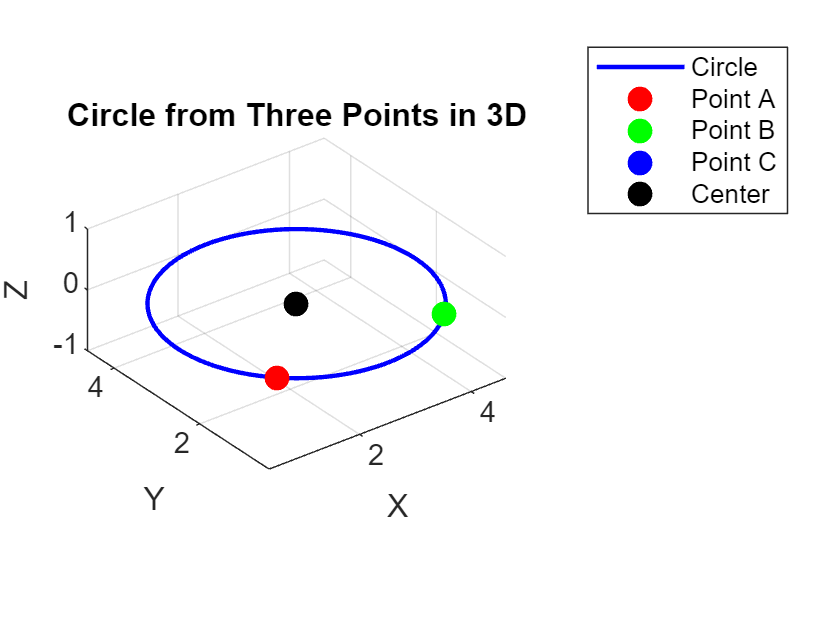

plotCircle3D(centerPoint.Position,circleRadius2,startPoint,endPoint,centerPoint)

function plotCircle3D(center, radius, p1, p2, p3)
    % Extract positions
    A = p1.Position;
    B = p2.Position;
    C = p3.Position;
    
    % Normal vector to the plane
    normal = cross(B - A, C - A);
    normal = normal / norm(normal);
    
    % Parametric circle equation in the plane
    theta = linspace(0, 2*pi, 100);
    v = null(normal); % Two orthogonal vectors in the plane
    
    % Circle points
    circlePoints = center' + radius * (v(:,1) * cos(theta) + v(:,2) * sin(theta));
    
    % Plot the circle
    plot3(circlePoints(1,:), circlePoints(2,:), circlePoints(3,:), 'b-', 'LineWidth', 1.5);
    hold on;
    
    % Plot the points
    plot3(A(1), A(2), A(3), 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');
    plot3(B(1), B(2), B(3), 'go', 'MarkerSize', 8, 'MarkerFaceColor', 'g');
    plot3(C(1), C(2), C(3), 'bo', 'MarkerSize', 8, 'MarkerFaceColor', 'b');
    
    % Plot the center
    plot3(center(1), center(2), center(3), 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k');
    
    % Labels
    legend('Circle', 'Point A', 'Point B', 'Point C', 'Center');
    xlabel('X');
    ylabel('Y');
    zlabel('Z');
    title('Circle from Three Points in 3D');
    grid on;
    axis equal;
    hold off;
end